# Wind Modelling using 32 Southwell Street Data

%Constants
Rho = 1.204; %kg/m^3
CpBetz = 0.593; %Betz max theoretical efficiency limit of a turbine
g = 1/40; %drag to lift ratio of the blade

%Losses - https://www.omnicalculator.com/ecology/wind-turbine
kw = 0.1; %Max wake losses due to neighbouring turbines
km = 0.003; %Max Mechanical losses of blade and gearbox
ke = 0.015; %Max Electrical losses
ket = 0.1; %Max Electrical losses during transmission
kt = 0.03; %Max percentage of time out of order for maintenance etc.


## Importing Data

opts = delimitedTextImportOptions("NumVariables", 33);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["name", "datetime", "tempmax", "tempmin", "temp", "feelslikemax", "feelslikemin", "feelslike", "dew", "humidity", "precip", "precipprob", "precipcover", "preciptype", "snow", "snowdepth", "windgust", "windspeed", "winddir", "sealevelpressure", "cloudcover", "visibility", "solarradiation", "solarenergy", "uvindex", "severerisk", "sunrise", "sunset", "moonphase", "conditions", "description", "icon", "stations"];
opts.VariableTypes = ["double", "datetime", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "categorical", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "datetime", "datetime", "double", "categorical", "categorical", "categorical", "categorical"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["preciptype", "conditions", "description", "icon", "stations"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "datetime", "InputFormat", "dd/MM/yyyy", "DatetimeFormat", "preserveinput");
opts = setvaropts(opts, "sunrise", "InputFormat", "yyyy-MM-dd'T'HH:mm:ss", "DatetimeFormat", "preserveinput");
opts = setvaropts(opts, "sunset", "InputFormat", "yyyy-MM-dd'T'HH:mm:ss", "DatetimeFormat", "preserveinput");
opts = setvaropts(opts, "name", "TrimNonNumeric", true);
opts = setvaropts(opts, "name", "ThousandsSeparator", ",");

% Import the data
southwellstreetbrist = readtable("32 southwell street brist... 2023-01-01 to 2024-01-01.csv", opts);
southwellstreetbrist(366,:) = [];
clear opts;

Heights = 20:10:150;
windspeeds = zeros(length(Heights),length(southwellstreetbrist.windspeed));
alpha = 0.6;

for i = 1:length(Heights)
    windspeeds(i,:) = southwellstreetbrist.windspeed./3.6.*((Heights(i)/10)^alpha);
end

windspeeds = windspeeds';
windspeeds = [southwellstreetbrist.windspeed./3.6, windspeeds];

Heights = 10:10:150;

WindSpeedsTable = array2table(windspeeds,"RowNames",cellstr(datetime(southwellstreetbrist.datetime)),"VariableNames",string(Heights+"m"));

mean(WindSpeedsTable(:,'10m'))


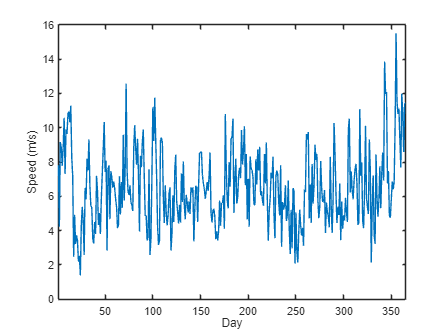

figure;

plot(1:length(table2array(WindSpeedsTable(:,"10m"))),table2array(WindSpeedsTable(:,"10m")));
%legend("Bristol Daily Wind Speeds 2023");
%fontsize(gca,24,"pixels");
ax = gca;
ax.YAxis.Exponent = 0;
ytickformat('%,.0f')
%xticks(Heights)
xlabel('Day')%,FontSize=28);
ylabel('Speed (m/s)')%,FontSize=28);
xlim([1 365]);
ax = gca;
exportgraphics(ax,'WindSpeeds.eps','Resolution',300) 

Darrieus VAWT Calcs

DarrieusLambda = 5; %https://www.nrel.gov/docs/fy11osti/50172.pdf
DarrieusCp = (1-g*DarrieusLambda)*CpBetz;
DarrieusEfficiency = (1-km)*(1-ke)*(1-ket)*(1-kt)*(1-kw)*DarrieusCp;

DarrieusHeight = Heights;

DarrieusDiameter = DarrieusHeight./4; %https://www.quora.com/How-can-I-get-the-height-and-diameter-of-the-Savonius-wind-turbine#:~:text=So%2Dcalled%20Savonius%20designs%20can,%3A1%20to%201.5%3A1.
DarrieusArea = DarrieusDiameter.*DarrieusHeight;

v0 = table2array(WindSpeedsTable);

DarrieusWindPower = 1/2*Rho.*(v0.^3).*DarrieusArea;

DarrieusOutputPower = DarrieusEfficiency.*DarrieusWindPower./(10^3); %Ouptut power in kW
DarrieusOutputPowerkWh =  array2table(DarrieusOutputPower,"RowNames",cellstr(datetime(southwellstreetbrist.datetime)),"VariableNames",string(Heights+"m")); %Ouput power in kWh for a day

Savonius VAWT Cals

SavoniusLambda = 1; %https://www.nrel.gov/docs/fy11osti/50172.pdf
SavoniusCp = (1-g*SavoniusLambda)*CpBetz;
SavoniusEfficiency = (1-km)*(1-ke)*(1-ket)*(1-kt)*(1-kw)*SavoniusCp;

SavoniusHeight = Heights;

SavoniusDiameter = SavoniusHeight./4; %https://www.quora.com/How-can-I-get-the-height-and-diameter-of-the-Savonius-wind-turbine#:~:text=So%2Dcalled%20Savonius%20designs%20can,%3A1%20to%201.5%3A1.
SavoniusArea = SavoniusDiameter.*SavoniusHeight;

v0 = table2array(WindSpeedsTable);

SavoniusWindPower = 1/2*Rho.*(v0.^3).*SavoniusArea;

SavoniusOutputPower = SavoniusEfficiency.*SavoniusWindPower./(10^3); %Ouptut power in kW
SavoniusOutputPowerkWh = array2table(SavoniusOutputPower,"RowNames",cellstr(datetime(southwellstreetbrist.datetime)),"VariableNames",string(Heights+"m")); %Ouput power in kWh for a day

HAWT Calcs

HAWTLambda = 8; %https://www.nrel.gov/docs/fy11osti/50172.pdf
HAWTCp = (1-g*HAWTLambda)*CpBetz;
HAWTEfficiency = (1-km)*(1-ke)*(1-ket)*(1-kt)*(1-kw)*HAWTCp;

HAWTHeight = Heights;

HAWTDiameter = (HAWTHeight-14.9)/0.789; %https://www.researchgate.net/figure/Development-of-rotor-diameter-and-hub-height-for-wind-turbines-installed-in-the_fig1_331565426
HAWTBladeLength = HAWTDiameter./3;
HAWTArea = pi.*HAWTBladeLength.^2;

v0 = table2array(WindSpeedsTable);

HAWTWindPower = 1/2.*Rho.*(v0.^3).*HAWTArea;

HAWTOutputPower = HAWTEfficiency.*HAWTWindPower./(10^3); %Ouptut power in kW
HAWTOutputPowerkWh = array2table(HAWTOutputPower,"RowNames",cellstr(datetime(southwellstreetbrist.datetime)),"VariableNames",string(Heights+"m")); %Ouput power in kWh for a day

Plotting

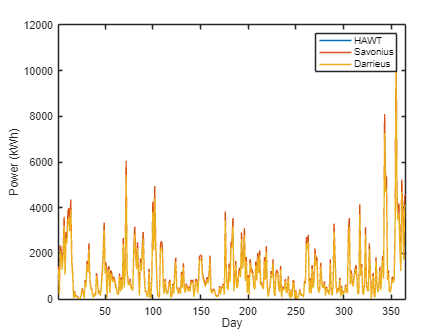

figure;

height = "50m";

hold on
plot(1:length(table2array(WindSpeedsTable(:,"10m"))),HAWTOutputPowerkWh.(height));
plot(1:length(table2array(WindSpeedsTable(:,"10m"))),SavoniusOutputPowerkWh.(height));
plot(1:length(table2array(WindSpeedsTable(:,"10m"))),DarrieusOutputPowerkWh.(height));
hold off
legend('HAWT','Savonius','Darrieus');
xlabel('Day');
ylabel('Power (kWh)');
xlim([1 365]);
box on
%title("Output Power (kWh) at a height of "+height);
ax = gca;
exportgraphics(ax,'PowerAtHeight.eps','Resolution',300) 

% Variation of wind over a day
% Occupancy Calcs

startDate = datetime('2023-01-01');
endDate = datetime('2023-12-31');
dates = startDate:endDate;

% Get full day names
dayNames = string(day(dates, 'name')); % 'dddd' gives full day names

% Create time strings (optional, if needed for another purpose)
times = hours(0:23);
timeStrings = string(datetime(2023,1,1) + times, 'HH:mm');  % Create datetime starting from a base date

% Preallocate the VarNames cell array
VarNames = cell(1, length(dates));

% Loop through each date and create formatted strings
for i = 1:length(dates)
    VarNames{i} = sprintf('%s: %s', datestr(dates(i), 'dd-mmm-yyyy'), dayNames(i));
end

%% Matrix Setup

DarrieusData = zeros(length(times),length(dates));
SavoniusData = zeros(length(times),length(dates));
HAWTData = zeros(length(times),length(dates));

%% Assigning wind percentage (wind speeds higher at middle of day):
x = linspace(0,2*pi,24);
DailyWind = (1-cos(x))/2;

% Transform to the range [0.5, 1.5]
DailyWind = DailyWind * (1.5 - 0.5) + 0.5;  % Scale to [0.5, 1.5]

mean(DailyWind)

ans = 0.9792

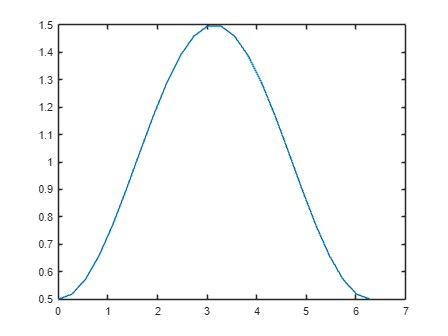


figure;
plot(x,DailyWind)


%Wind as a percentage as

for i=1:length(dates)
    DarrieusData(:,i) = DarrieusOutputPower(i,3)./24.*DailyWind;
    SavoniusData(:,i) = SavoniusOutputPower(i,3)./24.*DailyWind;
    HAWTData(:,i) = HAWTOutputPower(i,3)./24.*DailyWind;
end

HourlyDarrieusWind = array2table(DarrieusData,'RowNames',string(timeStrings),'VariableNames',string(VarNames));
HourlySavoniusWind = array2table(SavoniusData,'RowNames',string(timeStrings),'VariableNames',string(VarNames));
HourlyHAWTWind = array2table(HAWTData,'RowNames',string(timeStrings),'VariableNames',string(VarNames));

sum(sum(HourlyDarrieusWind),2)
sum(sum(HourlySavoniusWind),2)
sum(sum(HourlyHAWTWind),2)
sum(DarrieusOutputPowerkWh(:,"150m"))
sum(SavoniusOutputPowerkWh(:,"150m"))
sum(HAWTOutputPowerkWh(:,"150m"))

AllTypes = {};

AllTypes(:,1) = cellstr(Heights+"m");

DarrieusDataTemp = zeros(length(times),length(dates));
SavoniusDataTemp = zeros(length(times),length(dates));
HAWTDataTemp = zeros(length(times),length(dates));

for h=1:length(Heights)
    for i=1:length(dates)
        DarrieusDataTemp(:,i) = DarrieusOutputPower(i,h)./24.*DailyWind;
        SavoniusDataTemp(:,i) = SavoniusOutputPower(i,h)./24.*DailyWind;
        HAWTDataTemp(:,i) = HAWTOutputPower(i,h)./24.*DailyWind;
    end
    AllTypes(h,2) = {DarrieusDataTemp};
    AllTypes(h,3) = num2cell(sum(sum(DarrieusDataTemp),2));
    AllTypes(h,4) = {SavoniusDataTemp};
    AllTypes(h,5) = num2cell(sum(sum(SavoniusDataTemp),2));
    AllTypes(h,6) = {HAWTDataTemp};
    AllTypes(h,7) = num2cell(sum(sum(HAWTDataTemp),2));
end

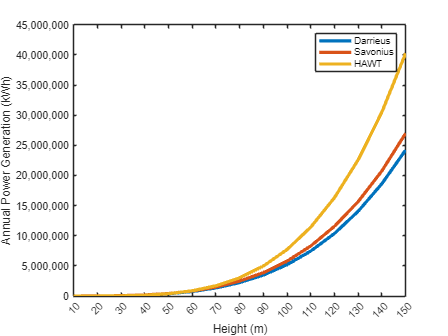

figure;

hold on
plot(Heights,cell2mat(AllTypes(:,3)),'LineWidth',3);
plot(Heights,cell2mat(AllTypes(:,5)),'LineWidth',3);
plot(Heights,cell2mat(AllTypes(:,7)),'LineWidth',3);
hold off
box on
legend('Darrieus','Savonius','HAWT');
%fontsize(gca,24,"pixels");
ax = gca;
ax.YAxis.Exponent = 0;
ytickformat('%,.0f')
xticks(Heights)
xlim([10 150])
xlabel("Height (m)")%,FontSize=28);
ylabel("Annual Power Generation (kWh)")%,FontSize=28);
ax = gca;
exportgraphics(ax,'WindTurbineTypesAtHeights.eps','Resolution',300) 

% Save specific variables a and b to a .mat file
save('../WindVariables.mat', 'HourlyDarrieusWind', 'HourlySavoniusWind','HourlyHAWTWind');